load('square_201.mat');
% figure;
% plot(u);
% grid on;

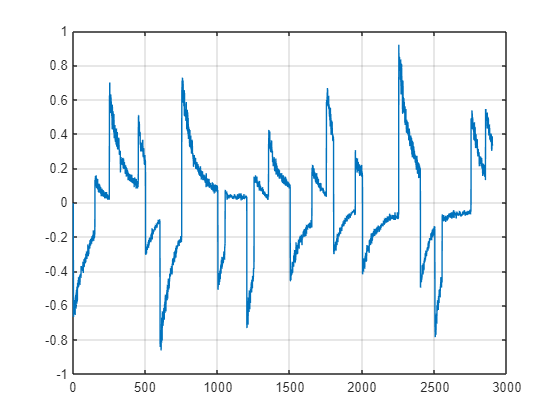

delay_estimate = 100;
initial_condition = [0; 0; 0;];

theta_offset = theta(1);
I_corrected = I_mot(delay_estimate+1:end);
theta_corrected = theta(delay_estimate+1:end) -  theta_offset;
phidot_corrected = phidot(delay_estimate+1:end);
u_real = u(delay_estimate+1:end);
theta_cal = theta_corrected*2*pi/4.5;

Ts = 0.01;
theta_dot = gradient(theta_cal, Ts);
y = [theta_cal, phidot_corrected];
%y = [theta_cal, phidot_corrected, I_corrected];
u = I_corrected;   
figure;
plot(u);
grid on;


N = length(u);
split_point = floor(2 * N / 3);  

u_train = u(1:split_point);
y_train = y(1:split_point, :);

u_val = u(split_point+1:end);
y_val = y(split_point+1:end, :);

data_id = iddata(y_train, u_train, 'Ts', 0.01);
Ts = 0.01;
opt = greyestOptions;
opt.InitialState =  initial_condition;

params_lin_init = {'J_theta', 0.3; 'mu_theta', 0.1224; 'J_phi', 0.001612; 'mu_phi', 0.000397;
    'kt', 0.3048; 'mgL', 1.353};


linear_model = idgrey('linear_reaction_pendulum', params_lin_init, 'c');
linear_model.Structure.Parameters(2).Free = false;
linear_model.Structure.Parameters(3).Free = false;
linear_model.Structure.Parameters(4).Free = false;
linear_model.Structure.Parameters(5).Free = false;
sys = greyest (data_id, linear_model, opt)

sys =
  Continuous-time linear grey box model defined by "linear_reaction_pendulum" function:
      dx/dt = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
             x1        x2        x3
   x1         0         0         1
   x2         0   -0.2463    0.2463
   x3    -3.203  0.002088   -0.6458
 
  B = 
           u1
   x1       0
   x2   189.1
   x3  -1.603
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1  -1
 
  D = 
       u1
   y1   0
   y2   0
 
  K = 
       y1  y2
   x1   0   0
   x2   0   0
   x3   0   0
 
  Model parameters:
   J_theta = 0.1901
   mu_theta = 0.1224
   J_phi = 0.001612
   mu_phi = 0.000397
   kt = 0.3048
   mgL = 0.609
 
Parameterization:
   ODE Function: linear_reaction_pendulum
   Disturbance component: none
   Initial state: fixed to double value
   Number of free coefficients: 2
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                               
Estimated using GREYE

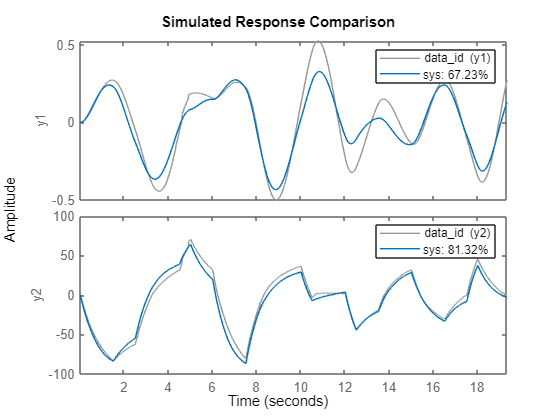


optcom = compareOptions;
optcom.InitialCondition = initial_condition;


figure;
compare(data_id,sys, optcom);

tspan = (0:length(u_train)-1) * Ts;
[y_sim, ~] = lsim(sys, u_train, tspan); 
vaf_theta = 100 * (1 - var(y_train(:,1) - y_sim(:,1)) / var(y_train(:,1)));
vaf_dphi  = 100 * (1 - var(y_train(:,2) - y_sim(:,2)) / var(y_train(:,2)));

fprintf('VAF of identification(theta): %.2f%%\n', vaf_theta);

VAF of identification(theta): 89.45%


fprintf('VAF of identification(dphi) : %.2f%%\n', vaf_dphi);

VAF of identification(dphi) : 97.11%


rmse_theta = sqrt(mean((y_train(:,1) - y_sim(:,1)).^2));
rmse_dphi  = sqrt(mean((y_train(:,2) - y_sim(:,2)).^2));

fprintf('RMSE of identification(theta): %.4f\n', rmse_theta);

RMSE of identification(theta): 0.0801


fprintf('RMSE of identification(dphi) : %.4f\n', rmse_dphi);

RMSE of identification(dphi) : 6.7595


optval = compareOptions;
% initial_condition = [0; 0; 0; 0];
optval.InitialCondition = [y_val(1,1); y_val(1,2); -0.25];
% initial_condition;
% [y_val(1,1); y_val(1,2); -0.25];

data_val = iddata(y_val, u_val, 'Ts', 0.01);
compare(data_val, sys, optval)
tspan = (0:length(u_val)-1) * Ts;
[y_sim, ~] = lsim(sys, u_val, tspan); 
vaf_theta = 100 * (1 - var(y_val(:,1) - y_sim(:,1)) / var(y_val(:,1)));
vaf_dphi  = 100 * (1 - var(y_val(:,2) - y_sim(:,2)) / var(y_val(:,2)));

fprintf('VAF of validation(theta): %.2f%%\n', vaf_theta);
fprintf('VAF of validation(dphi) : %.2f%%\n', vaf_dphi);
rmse_theta = sqrt(mean((y_val(:,1) - y_sim(:,1)).^2));
rmse_dphi  = sqrt(mean((y_val(:,2) - y_sim(:,2)).^2));

fprintf('RMSE of validation(theta): %.4f\n', rmse_theta);
fprintf('RMSE of validation(dphi) : %.4f\n', rmse_dphi);

optval = compareOptions;
optval.InitialCondition = initial_condition;
% initial_condition;
% [y_val(1,1); y_val(1,2); -0.25];

data_val = iddata(y, u, 'Ts', 0.01);
compare(data_val, sys, optval)
tspan = (0:length(u)-1) * Ts;
[y_sim, t] = lsim(sys, u, tspan); 
vaf_theta = 100 * (1 - var(y(:,1) - y_sim(:,1)) / var(y(:,1)));
vaf_dphi  = 100 * (1 - var(y(:,2) - y_sim(:,2)) / var(y(:,2)));

fprintf('VAF of validation(theta): %.2f%%\n', vaf_theta);
fprintf('VAF of validation(dphi) : %.2f%%\n', vaf_dphi);
rmse_theta = sqrt(mean((y(:,1) - y_sim(:,1)).^2));
rmse_dphi  = sqrt(mean((y(:,2) - y_sim(:,2)).^2));

fprintf('RMSE of validation(theta): %.4f\n', rmse_theta);
fprintf('RMSE of validation(dphi) : %.4f\n', rmse_dphi);

Order = [2 1 3];   % [#outputs, #inputs, #states]
Ts = 0.01;              
kt = 0.6139;
mu_phi = 0.0008027;
mu_theta = 0.2471;
J_phi = 0.0032;
J_theta = 0.3;
mgL = 3.436;

% params_lin_init = {'J_theta', 0.89; 'mu_theta', 0.33; 'J_phi', 0.00492; 'mu_phi', 0.007535;
%     'kt', -0.9648; 'mgL', 1.353};


% 
% parameters    = {J_theta, mu_theta, J_phi, mu_phi, kt, mgL};
% 
% initial_states = initial_condition;
% nlgr = idnlgrey('reaction_pendulum_model', Order, parameters, initial_states, Ts);
% nlgr = setpar(nlgr,'Minimum',{eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) });
% nlgr = setpar(nlgr,'Fixed',{true true true true true true});
% data = iddata(y_train, u_train, 'Ts', 0.01);
% 
% % % nlgr.SimulationOptions.Solver = 'ode23';
% % 
% % % nlgr.Parameters(1).Fixed = true;
% % % nlgr.Parameters(4).Fixed = true;
% % % nlgr.Parameters(5).Fixed = true;
% % 
% % opt = nlgreyestOptions;
% % opt.Display = 'on';
% % %opt.SearchMethod = 'lsqnonlin';  
% % opt.SearchOptions.MaxIterations = 200;
% % 
% % estimated_model = nlgreyest(data, nlgr,'Display','Full')
% % 
% % getpvec(estimated_model)
tspan = (0:length(u_train)-1) * Ts;
u_interp = @(t) interp1(tspan, u_train, t, 'linear', 'extrap');
odefun = @(t, x) reaction_pendulum_model(t, x, u_interp(t), ...
    J_theta, mu_theta, J_phi, mu_phi, kt, mgL);
x0 = [0; 0; 0];  
[t_out, x_out] = ode45(odefun, tspan, x0);
y_sim = x_out(:, [1 2]);  

figure;
subplot(2,1,1);
plot(tspan, y_train(:,1), 'b', t_out, y_sim(:,1), 'r--');
legend('Measured \theta','Simulated \theta');
ylabel('\theta (rad)');

subplot(2,1,2);
plot(tspan, y_train(:,2), 'b', t_out, y_sim(:,2), 'r--');
legend('Measured d\phi','Simulated d\phi');
xlabel('Time (s)');
ylabel('d\phi (rad/s)');
vaf_theta = 100 * (1 - var(y_train(:,1) - y_sim(:,1)) / var(y_train(:,1)));
vaf_dphi  = 100 * (1 - var(y_train(:,2) - y_sim(:,2)) / var(y_train(:,2)));

fprintf('VAF (theta): %.2f%%\n', vaf_theta);
fprintf('VAF (dphi) : %.2f%%\n', vaf_dphi);



% figure;
% compare(data,reaction_pendulum_model,optcom)

% A = sys.A;
% A(3,1) = -A(3,1);
% B = sys.B;
% C = sys.C;
% D = sys.D;
% linear_sys = ss(A, B, C, D);
% 
% sys_min = minreal(linear_sys);

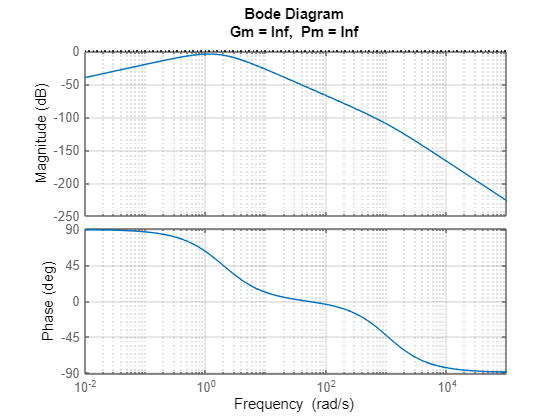

A = connected.A;
%A(3,1) = -A(3,1);
B = connected.B;
C = connected.C;
D = connected.D;
[num, den] = ss2tf(A, B, C, D, 1);
linear_sys = ss(A, B, C, D);

sys_min = minreal(linear_sys);
siso_sys = sys_min(1, 1);


figure;
margin(siso_sys);
grid on;

[mag, phase, omega] = bode(siso_sys);
mag = squeeze(mag); 
omega = squeeze(omega); 
mag_db = 20*log10(mag); 
index_3db = find(mag_db <= -3, 1, 'first'); 
bw = omega(index_3db);
disp(['Bandwidth: ', num2str(bw), ' rad/s']);

Bandwidth: 0.1 rad/s


% figure;
% step(siso_sys);
% title('Step Response');
% grid on;


Kp = 1; 
Ki = 0; 
Kd = 0; 
Tf = 1; 
pid_controller = Kp + tf([0 Ki], [1 0]) + tf([Kd 0], [Tf 1]);
open_loop = pid_controller * siso_sys;
closed_loop = feedback(open_loop, 1);

[GM, PM, Wcg, Wcp] = margin(open_loop);

disp(['Gain Margin (dB): ', num2str(20*log10(GM))]);

Gain Margin (dB): Inf


disp(['Phase Margin (degrees): ', num2str(PM)]);

Phase Margin (degrees): Inf


disp(['Gain Crossover Frequency (rad/s): ', num2str(Wcg)]);

Gain Crossover Frequency (rad/s): NaN


disp(['Phase Crossover Frequency (rad/s): ', num2str(Wcp)]);

Phase Crossover Frequency (rad/s): NaN



[mag, ~, omega] = bode(open_loop);
mag = squeeze(mag);
omega = squeeze(omega);
mag_db = 20*log10(mag);
index_bw = find(mag_db <= -3, 1, 'first'); 
bw = omega(index_bw);
disp(['Bandwidth: ', num2str(bw), ' rad/s']);

Bandwidth: 0.1 rad/s


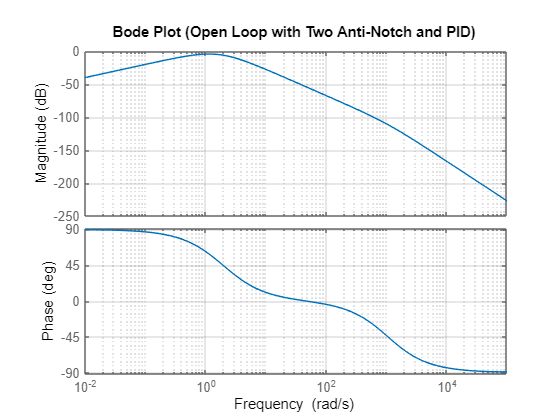


figure;
bode(open_loop);
grid on;
title('Bode Plot (Open Loop with Two Anti-Notch and PID)');

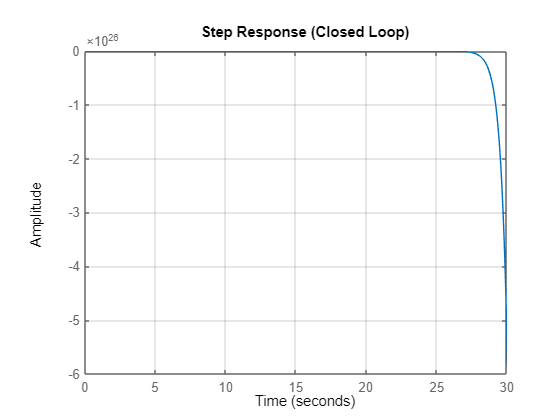


figure;
step(closed_loop);
grid on;
title('Step Response (Closed Loop)');

q = [1, 3, 1, 0.0001];
Q = 1 * diag(q);
% Q = 1e-5 * eye(4);  
r = [0.1, 1, 10];
R = 1 * diag(r);   
G = zeros(4);

sys_d = c2d(linear_sys, 0.01);
Ad = sys_d.A;
Bd = sys_d.B;
Cd = sys_d.C;
Dd = sys_d.D;

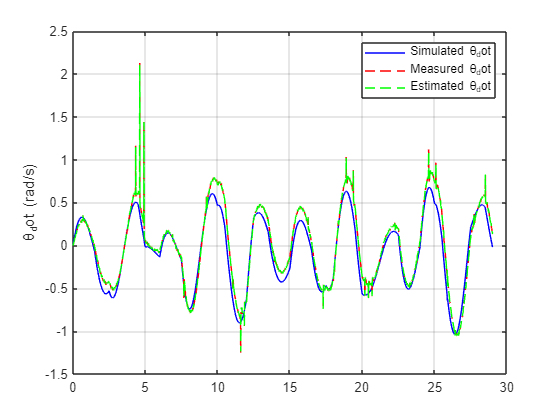

n = size(Ad,1);
xhat = zeros(n, 1);          
P = 0*eye(n);   
N = length(y);
for k = 1:N
    xhat_pred = Ad * xhat + Bd * u_real(k,:)';
    P_pred = Ad * P * Ad' + Q;

    y_pred = Cd * xhat_pred;
    K = P_pred * Cd' / (Cd * P_pred * Cd' + R);   

    xhat = xhat_pred + K * (y(k,:)' - y_pred);  
    P = (eye(n) - K * Cd) * P_pred;             

    xhat_all(:,k) = xhat;  
end



% xhat = zeros(4, N); 
% xhat(:,1) = zeros(4,1);
% for k = 1:N-1
%     xhat(:,k+1) = A * xhat(:,k) + B * u_real(k,:)' + L * (y(k,:)' - C * xhat(:,k));
% end

Tf = Ts*(length(y)-1);
T= 0:Ts:Tf;
N = length(y);
% xhat_corrected = xhat(delay_estimate+1:end, :);
% theta_dotest = gradient(xhat_corrected(:,2), Ts);
theta_dotest = gradient(xhat_all(2,:), Ts);
figure;
plot(T, xhat_all(4,:)', 'b');
hold on;
plot(T, theta_dot(:,1), 'r--');
plot(T, theta_dotest(1,:)', 'g--');
grid on;
legend('Simulated \theta_dot','Measured \theta_dot','Estimated \theta_dot');
ylabel('\theta_dot (rad/s)');

vaf_theta = 100 * (1 - var(theta_cal(:,1) - xhat_all(2,:)') / var(theta_cal(:,1)))

vaf_theta = 100.0000

vaf_phidot = 100 * (1 - var(phidot_corrected(:,1) - xhat_all(3,:)') / var(phidot_corrected(:,1)))

vaf_phidot = 99.9794

vaf_Imot = 100 * (1 - var(I_corrected(:,1)/54.6280805648926 - xhat_all(1,:)') / var(I_corrected(:,1)))

vaf_Imot = 100.0000

vaf_thetadot = 100 * (1 - var(theta_dot(:,1) - xhat_all(4,:)') / var(theta_dot(:,1)))

vaf_thetadot = 93.5751

q = [1, 3, 10, 0.18];
Q = 1 * diag(q);
% Q = 1e-5 * eye(4);  
r = [0.01, 0.1, 0.1, 0.0001];
R = 1 * diag(r);   
G = zeros(4);

% Ad = connected.A;
% Bd = connected.B;
% Cd = connected.C;
% Dd = connected.D;
load('kalman_2.mat');
sys_d = c2d(linear_sys, 0.01);
Ad = sys_d.A;
Bd = sys_d.B;
Cd = sys_d.C;
Dd = sys_d.D;


theta_dot = gradient(theta, Ts);

Unrecognized function or variable 'Ts'.

y = [theta, phidot, I_mot, theta_dot];
u_real = u;
n = size(Ad,1);
xhat = zeros(n, 1);          
P = 0*eye(n);   
N = length(y);
xhat_all = [];
for k = 1:N
    xhat_pred = Ad * xhat + Bd * u_real(k,:)';
    P_pred = Ad * P * Ad' + Q;

    y_pred = Cd * xhat_pred;
    K = P_pred * Cd' / (Cd * P_pred * Cd' + R);   

    xhat = xhat_pred + K * (y(k,:)' - y_pred);  
    P = (eye(n) - K * Cd) * P_pred;             

    xhat_all(:,k) = xhat;  
end



% xhat = zeros(4, N); 
% xhat(:,1) = zeros(4,1);
% for k = 1:N-1
%     xhat(:,k+1) = A * xhat(:,k) + B * u_real(k,:)' + L * (y(k,:)' - C * xhat(:,k));
% end

Tf = Ts*(length(y)-1);
T= 0:Ts:Tf;
N = length(y);
% xhat_corrected = xhat(delay_estimate+1:end, :);
% theta_dotest = gradient(xhat_corrected(:,2), Ts);
theta_dotest = gradient(xhat_all(2,:), Ts);
figure;
plot(T, xhat_all(4,:)', 'b');
hold on;
plot(T, theta_dot(:,1), 'r--');
plot(T, theta_dotest(1,:)', 'g--');
grid on;
legend('Simulated \theta_dot','Measured \theta_dot','Estimated \theta_dot');
ylabel('\theta_dot (rad/s)');
vaf_theta = 100 * (1 - var(theta(:,1) - xhat_all(2,:)') / var(theta_cal(:,1)))
vaf_phidot = 100 * (1 - var(phidot(:,1) - xhat_all(3,:)') / var(phidot_corrected(:,1)))
vaf_Imot = 100 * (1 - var(I_mot(:,1)/54.6280805648926 - xhat_all(1,:)') / var(I_corrected(:,1)))
vaf_thetadot = 100 * (1 - var(theta_dot(:,1) - xhat_all(4,:)') / var(theta_dot(:,1)))

Q_lqr = diag([0.0001, 10, 0.001, 0.001]);
R_lqr = 0.0001;
N_lqr = zeros(4, 1);

[K, S, P] = dlqr(Ad, Bd, Q_lqr, R_lqr, N_lqr)

K =     2.1964 -115.3679   -0.2233  -52.6774


S = 	1.0e+03 *

    0.0000   -0.0021   -0.0000   -0.0010
   -0.0021    8.7789    0.0342    4.0489
   -0.0000    0.0342    0.0001    0.0162
   -0.0010    4.0489    0.0162    1.9184


P =     0.9867
    0.9763
   -0.0981
   -0.0000


Np = 10;
Nc = 5;

mpcobj = mpc(sys_d, Ts, Np, Nc);
mpcobj.Weights.ManipulatedVariables = [0.0001];      
% mpcobj.Weights.ManipulatedVariablesRate = [0.01];
mpcobj.Weights.OutputVariables = [0.0001, 10, 0.001, 0.001];        

mpcobj.MV(1).Min = -1;
mpcobj.MV(1).Max = 1;

mpcobj.OV(1).Min = -(10/180)*pi;
mpcobj.OV(1).Max = (10/180)*pi;
% mpcobj.OV(2).Min = -100;
% mpcobj.OV(2).Max = 100;

mpcobj.Model.Nominal.X = [0; 0; 0; 0];
mpcobj.Model.Nominal.U = 0;
mpcobj.Model.Nominal.Y = [0; 0; 0; 0];
state = mpcstate(mpcobj);
